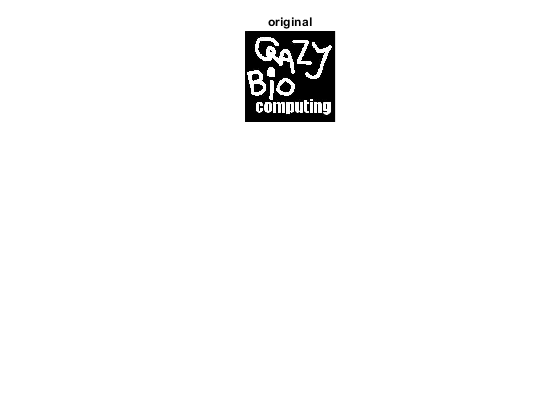

I = imread('crazyBioComp.jpg');
fig = figure();
subplot(3,3,2)
imshow(I)
title('original')

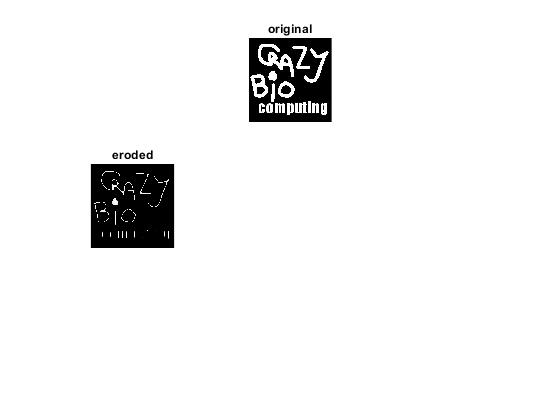

SE1 = strel('disk',5);
I_eroded = imerode(I,SE1);
subplot(3,3,4)
imshow(I_eroded)
title('eroded')

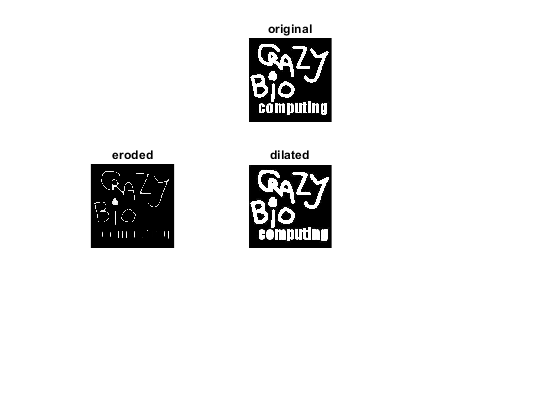

SE1 = strel('cube',2);
I_dilated = imdilate(I,SE1);
subplot(3,3,5)
imshow(I_dilated)
title('dilated')

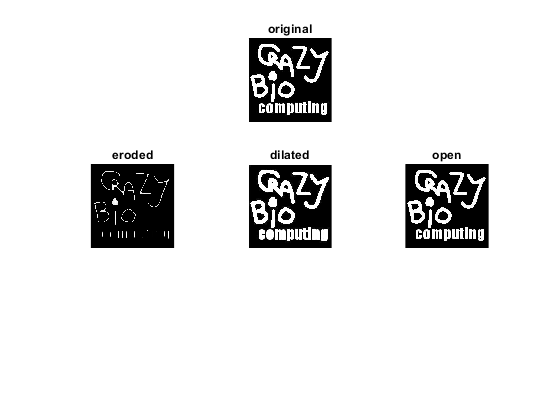

I_open = imopen(I,SE1);
subplot(3,3,6)
imshow(I_open)
title('open')

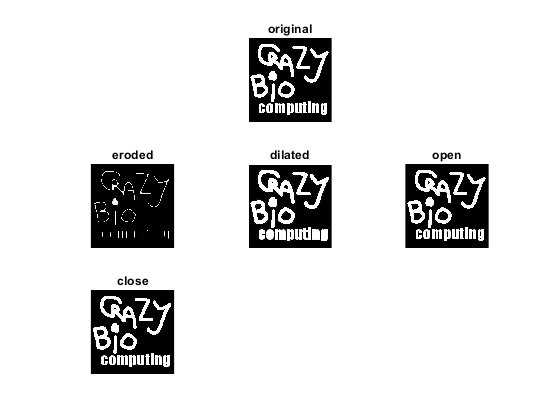

I_close = imclose(I,SE1);
subplot(3,3,7)
imshow(I_open)
title('close')

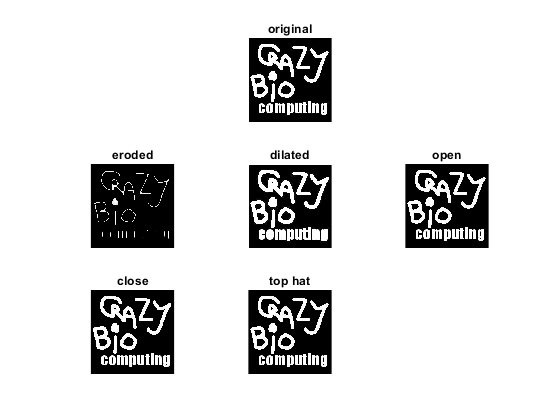

I_tophat = imtophat(I,SE1);
subplot(3,3,8)
imshow(I_open)
title('top hat')

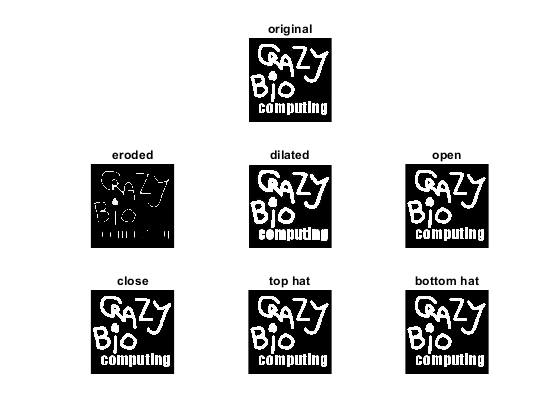

I_bothat = imbothat(I,SE1);
subplot(3,3,9)
imshow(I_open)
title('bottom hat')

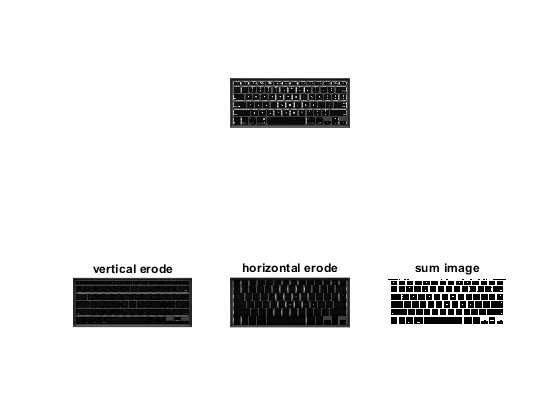

I2 = imread('keyboard.jpg');
fig = figure;
subplot(2,3,2);
imshow(I2)
SE2 = strel('line',8,0);
SE3 = strel('line',8,90);
SE4 = strel('square',8);
I_erode1 = imerode(I2,SE2);
subplot(2,3,4);
imshow(I_erode1)
title('vertical erode')
I_erode2 = imerode(I2,SE3);
subplot(2,3,5);
imshow(I_erode2)
title('horizontal erode')
sum_I = I_erode1 + I_erode2;
sum_I = im2bw(sum_I,0.2);
subplot(2,3,6);
imshow(sum_I)
title('sum image')
saveas(fig,'Q1-3.jpg')

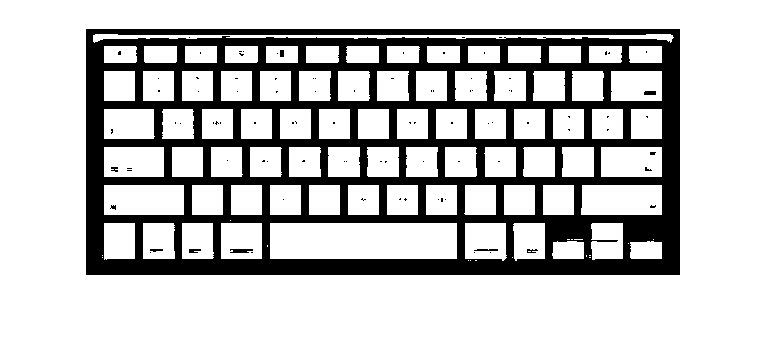

I2 = imread('keyboard.jpg');
I2_not = ~sum_I;
fig = figure;
imshow(I2_not)

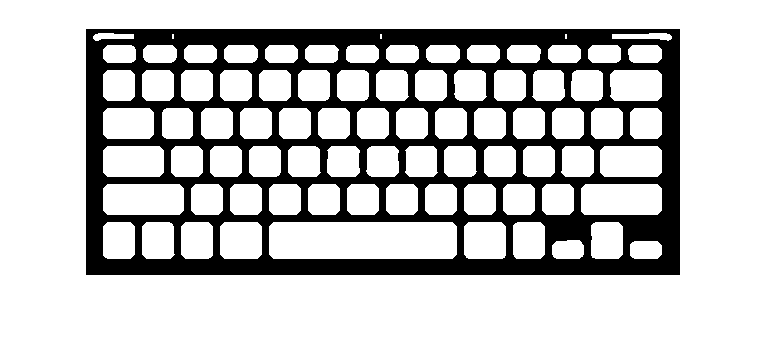

filtered = medfilt2(I2_not,[8 8]);
imshow(filtered)

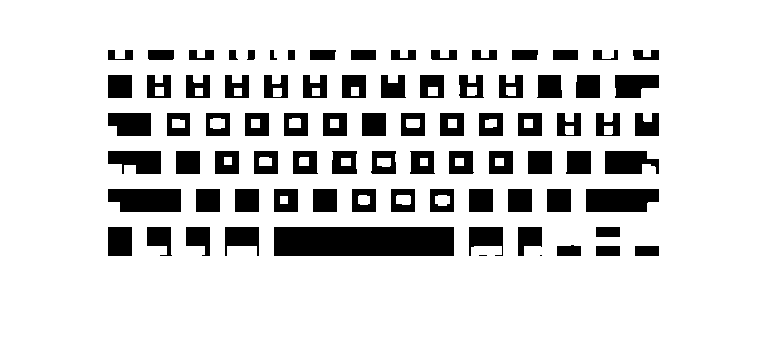

sum_I_dilate = imdilate(sum_I,SE4);
imshow(sum_I_dilate)

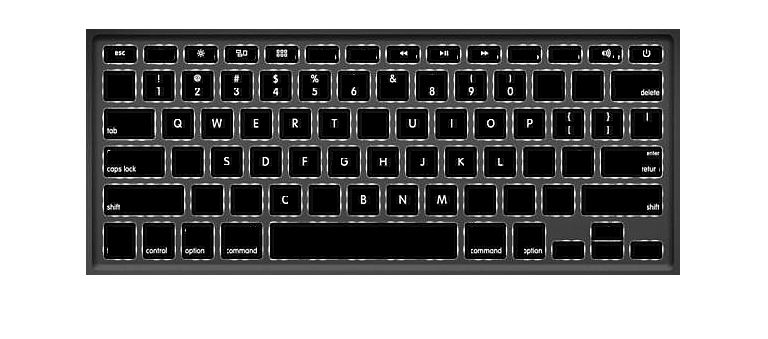

total_im = uint8(sum_I_dilate).*I2;
total_im = imsharpen(total_im);
imshow(total_im)

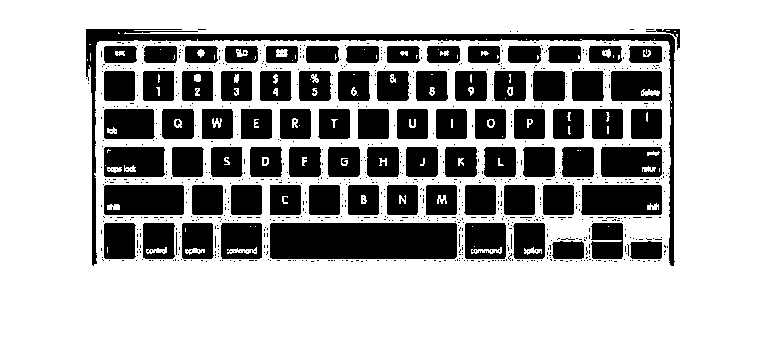

imshow(im2bw(total_im,0.2))